clear all
clc

inp = 'inputfile_fracture';
eval(inp);

[U,E,S,S33,history] = sol_nlFEM_18(inp);

    "timedate:"    "09-Nov-2020 07:22:09"

**Analysis information**
Nonlinear FEM, Plane strain formulation.
Solver type:  Quasi-Newton algorithm
sol_nlFEM_18() solver version 1.8; rev. date: 2-Aug-2020
5%
10%
15%
20%
25%
30%
35%
40%
45%
50%
55%
60%
65%
70%
75%
80%
85%
90%
95%
100%
Elapsed time is 28230.739720 seconds.


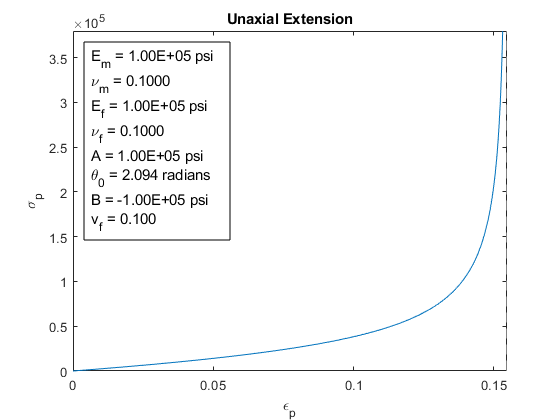

snodes = extrapnodesV1_4(Iorder, size(nodes,2), S, elements);
enodes = extrapnodesV1_4(Iorder, size(nodes,2), E, elements);

U1 = U(1:2:length(U));
U2 = U(2:2:length(U));

elock = 1/sin(theta0/2)-1; %create elock for plotting.

fsig1 = @(A,B,E_f,E_m,e11,e22,e33,nu_f,nu_m,theta0,v_f)(v_f.*sin(theta0./2.0).*1.0./sqrt(1.0-sin(theta0./2.0)...
     .^2.*(e11+1.0).^2).*(theta0-asin(sin(theta0./2.0).*(e11+1.0)).*2.0).*-2.0).*A+((v_f.*sin(theta0./2.0)...
     .*1.0./sqrt(-sin(theta0./2.0).^2.*(e11+1.0).^2+1.0).*(theta0-asin(sin(theta0./2.0).*(e11+1.0)).*2.0))./...
     (theta0.*asin(sin(theta0./2.0).*(e11+1.0)))).*B+(v_f.*((e22.^2.*sin(theta0./2.0).^4.*(E_f-E_m)...
     .*(e11+1.0).^3.*(nu_f-1.0).*2.0)./(nu_f+nu_f.^2.*2.0-1.0)+(e22.*e33.*nu_f.*(E_f-E_m)...
     .*(cos(theta0)./2.0-1.0./2.0).*(e11+1.0).*2.0)./((nu_f.*2.0-1.0).*(nu_f+1.0)))+(E_m.*(v_f-1.0)...
     .*(e11-e11.*nu_m+e22.*nu_m+e33.*nu_m))./(nu_m+nu_m.^2.*2.0-1.0));
syms e11 
figure;
fplot(fsig1(Ax,Bx,E_f,E_m,e11,0,0,nu_f,nu_m,theta0,v_f),[0 elock])
xlabel('\epsilon_{p}')
ylabel('\sigma_{p}')
title('Unaxial Extension')
str = {['E_m = ' num2str(E_m,'%1.2E') ' psi'],...
    ['\nu_{m} = ' num2str(nu_m,'%1.4f')],['E_f = ' num2str(E_f,'%1.2E') ' psi'],['\nu_{f} = ' num2str(nu_f,'%1.4f')],...
    ['A = ' num2str(Ax,'%1.2E') ' psi' ], ['\theta_{0} = ' num2str(theta0,'%1.3f') ' radians'], ['B = ' num2str(Bx,'%1.2E') ' psi'],...
    ['v_{f} = ' num2str(v_f,'%1.3f')]};
dim = [.15 .60 .3 .3];
annotation('textbox',dim,'String',str,'FitBoxToText','on','BackgroundColor','white','fontSize',11)

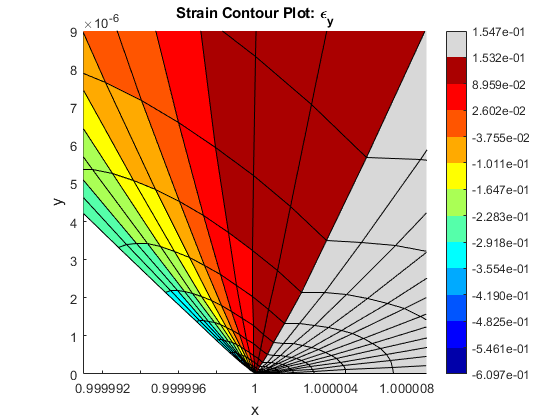



zoomradius = 9e-6;

% contourPlotV1_2(1, [], [], 'E', nodes, elements, snodes, enodes, Iorder, U, S, E)
contourPlotV1_2(2, [], 0.99*elock, 'E', nodes, elements, snodes, enodes, Iorder, U, S, E)
axis square
axis([1-zoomradius 1+zoomradius 0 zoomradius])

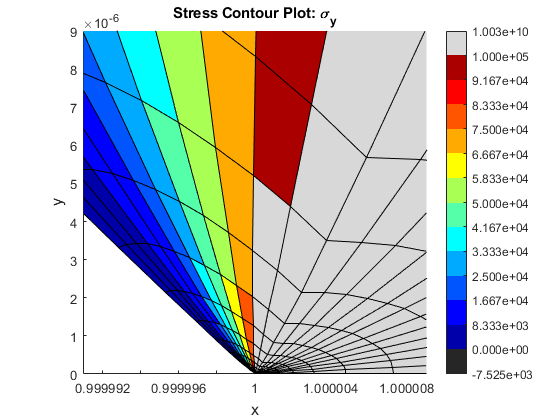


contourPlotV1_2(2, 0, 1e5, 'S', nodes, elements, snodes, enodes, Iorder, U, S, E)
axis square
axis([1-zoomradius 1+zoomradius 0 zoomradius])

% contourPlotV1_2(3, 0, [], 'E', nodes, elements, snodes, enodes, Iorder, U, S, E)
% 
% contourPlotV1_2(1, [], [], 'S', nodes, elements, snodes, enodes, Iorder, U, S, E)
% contourPlotV1_2(2, [], [], 'S', nodes, elements, snodes, enodes, Iorder, U, S, E)
% contourPlotV1_2(3, [], [], 'S', nodes, elements, snodes, enodes, Iorder, U, S, E)

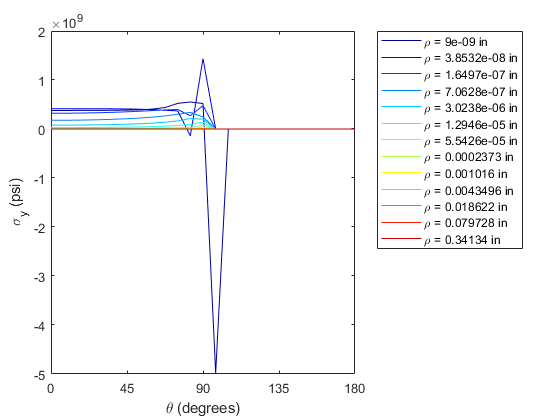

num_th = 3; %1 for all thetas, 2 for half, etc.

figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
rhovals = vecnorm(nodes(:,rhos(:,1))-origin');
rhos_ind = rhos;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i) mean(snodes(2,elements == rhos_ind(r,i)))];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel('\sigma_{y} (psi)')
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

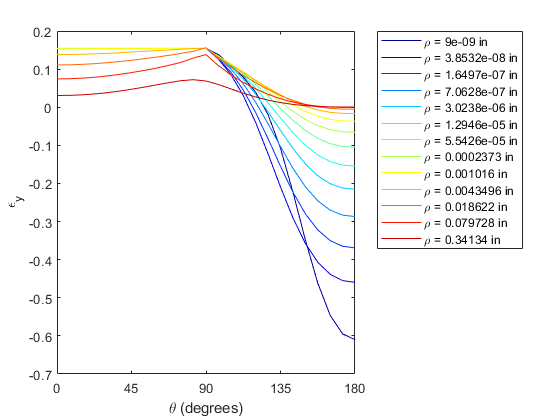


figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
rhovals = vecnorm(nodes(:,rhos(:,1))-origin');
rhos_ind = rhos;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i) mean(enodes(2,elements == rhos_ind(r,i)))];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel('\epsilon_{y}')
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

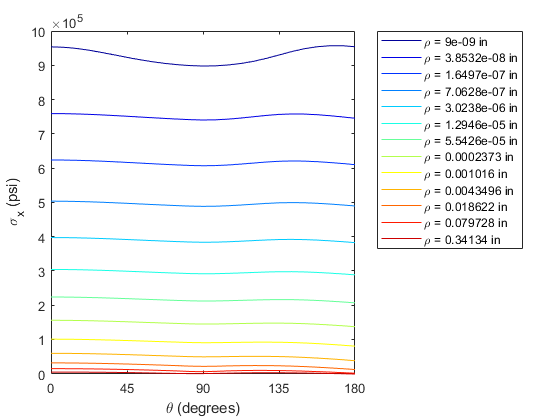


figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
rhovals = vecnorm(nodes(:,rhos(:,1))-origin');
rhos_ind = rhos;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i) mean(snodes(1,elements == rhos_ind(r,i)))];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel('\sigma_{x} (psi)')
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

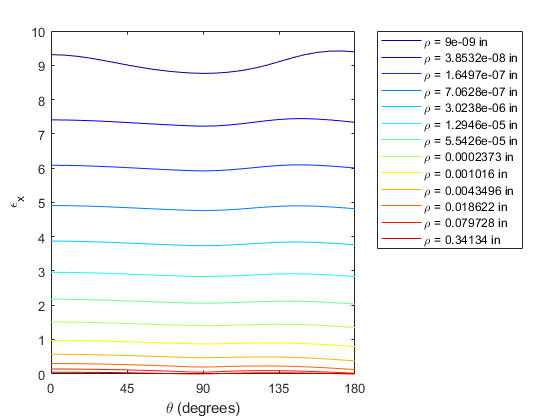


figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
rhovals = vecnorm(nodes(:,rhos(:,1))-origin');
rhos_ind = rhos;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i) mean(enodes(1,elements == rhos_ind(r,i)))];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel('\epsilon_{x}')
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

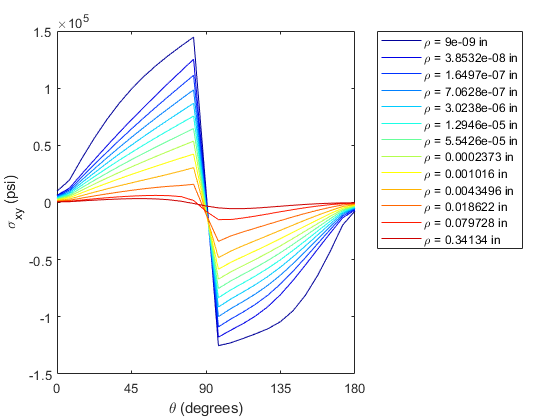


figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
rhovals = vecnorm(nodes(:,rhos(:,1))-origin');
rhos_ind = rhos;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i) mean(snodes(3,elements == rhos_ind(r,i)))];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel('\sigma_{xy} (psi)')
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

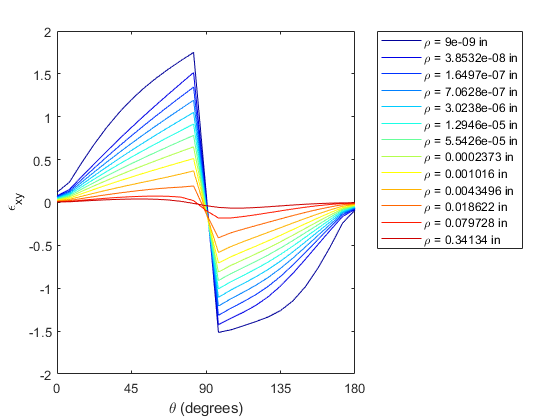


figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
rhovals = vecnorm(nodes(:,rhos(:,1))-origin');
rhos_ind = rhos;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i) mean(enodes(3,elements == rhos_ind(r,i)))];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel('\epsilon_{xy}')
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

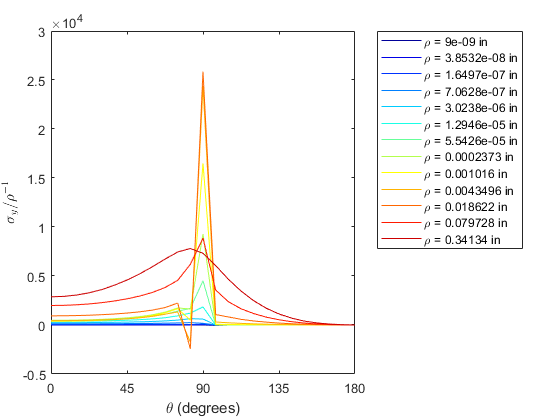


figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i)...
            mean(snodes(2,elements == rhos_ind(r,i)))...
            /vecnorm(nodes(:,rhos_ind(r,i))-origin')^(-1)];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel('$\sigma_{y}/\rho^{-1}$', 'Interpreter',"latex")
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

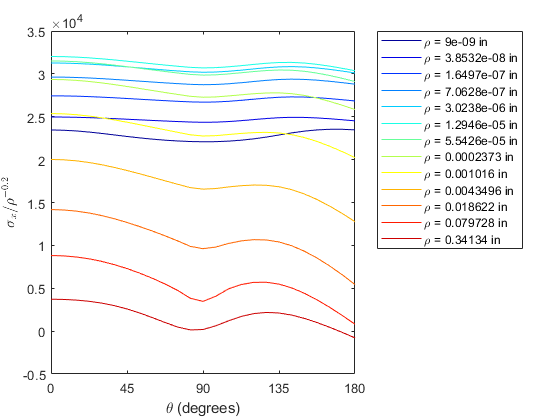


Cstar = Cmat_transvIsoV3b(2, [0 elock 0], E_m, nu_m, Ax, Bx, theta0, E_f, nu_f, v_f);
order = -1/5;

figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i)...
            mean(snodes(1,elements == rhos_ind(r,i)))...
            /vecnorm(nodes(:,rhos_ind(r,i))-origin')^(order)];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel(['$\sigma_{x}/\rho^{' num2str(order) '}$'], 'Interpreter',"latex")
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

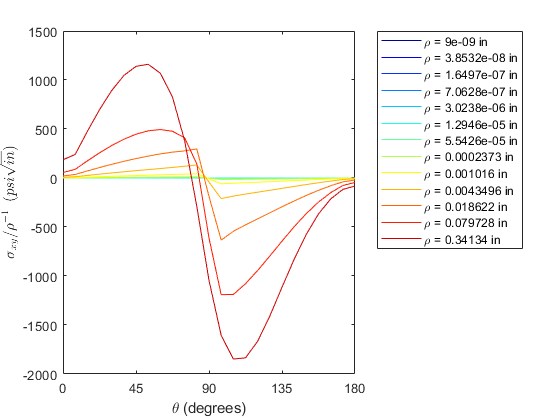

%######################################
% figure;
% plotdata = [];
% thetas = 0:180/(4*ndivs):180;
% cmap = colormap(jet(size(rhos_ind,1)));
% for r = 2:6
%     for i = 1:size(rhos_ind,2)
%         plotdata(i,:) = [thetas(i)...
%             (mean(snodes(1,elements == rhos_ind(r,i))) - Cstar(1,2)*elock)...
%             /(vecnorm(nodes(:,rhos_ind(r,i))-origin')^(-.25)*Cstar(1,1))];
%     end
%     plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
%     hold on
% end
% hold off
% xlabel('\theta (degrees)')
% ylabel('$f_{\epsilon_{xx}}(\theta)$', 'Interpreter',"latex")
% xlim([0 180])
% xticks(0:45:180)
% legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(2:6,1))-origin'))+" in",'Location',"bestoutside")
%#####################################################

figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:num_th:size(rhos_ind,1)
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i)...
            mean(snodes(3,elements == rhos_ind(r,i)))...
            /vecnorm(nodes(:,rhos_ind(r,i))-origin')^(-1)];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
hold off
xlabel('\theta (degrees)')
ylabel('$\sigma_{xy}/\rho^{-1} \enspace (psi{\sqrt{in}})$', 'Interpreter',"latex")
xlim([0 180])
xticks(0:45:180)
legend("\rho = "+string(vecnorm(nodes(:,rhos_ind(1:num_th:size(rhos_ind,1),1))-origin'))+" in",'Location',"bestoutside")

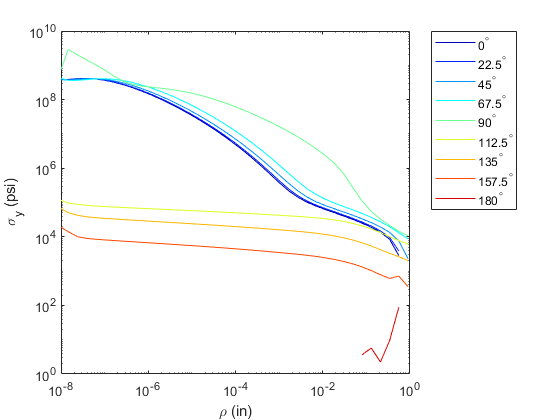


figure;
nodes_loc = nodes-origin';
plotdata = [];
cmap = colormap(jet(size(rhos_ind,2)));
for c = 1:num_th:size(rhos_ind,2)
    for i = 1:size(rhos_ind,1)
        plotdata(i,:) = [norm(nodes_loc(:,rhos_ind(i,c))) mean(snodes(2,elements == rhos_ind(i,c)))];
    end
    loglog(plotdata(:,1),plotdata(:,2),'Color',cmap(c,:))
    hold on
    if c == 1
        ft = fittype('m*x + b');
        f1 = fit(log10(plotdata(:,1)),log10(plotdata(:,2)),ft);
    end
end
hold off
axis([1e-8 1e0 1e0 1e10])
legend(string(thetas(1:num_th:length(thetas)))+'^\circ','Location','bestoutside')
xlabel('\rho (in)')
ylabel('\sigma_{y} (psi)')

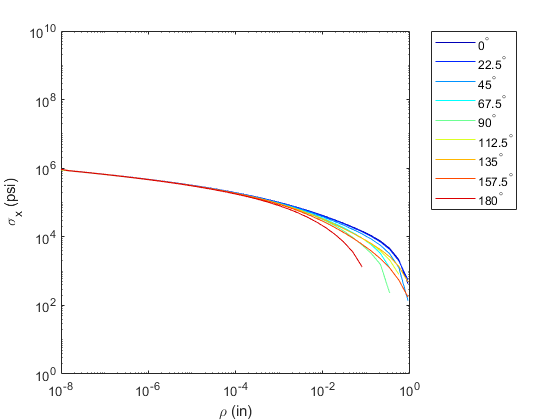



figure;
nodes_loc = nodes-origin';
plotdata = [];
cmap = colormap(jet(size(rhos_ind,2)));
for c = 1:num_th:size(rhos_ind,2)
    for i = 1:size(rhos_ind,1)
        plotdata(i,:) = [norm(nodes_loc(:,rhos_ind(i,c))) mean(snodes(1,elements == rhos_ind(i,c)))];
    end
    loglog(plotdata(:,1),plotdata(:,2),'Color',cmap(c,:))
    hold on
    if c == 1
        ft = fittype('m*x + b');
        f1 = fit(log10(plotdata(:,1)),log10(plotdata(:,2)),ft);
    end
end
hold off
axis([1e-8 1e0 1e0 1e10])
legend(string(thetas(1:num_th:length(thetas)))+'^\circ','Location','bestoutside')
xlabel('\rho (in)')
ylabel('\sigma_{x} (psi)')

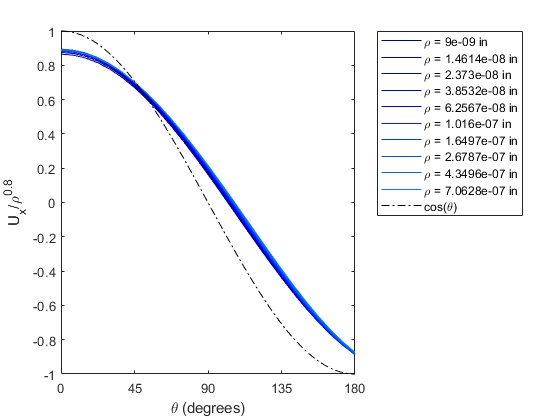


figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
rhovals = vecnorm(nodes(:,rhos(:,1))-origin');
rhos_ind = rhos;
cmap = colormap(jet(size(rhos_ind,1)));
k=10;
for r = 1:k
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i) U1(rhos_ind(r,i))/(vecnorm(nodes(:,rhos_ind(r,i))-origin'))^(.868)];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
plot(0:180,cos(deg2rad(0:180)),'k-.')
hold off
xlabel('\theta (degrees)')
ylabel(['U_{x}/\rho^{' num2str(order+1) '}'])
xlim([0 180])
xticks(0:45:180)
legend(["\rho = "+string(vecnorm(nodes(:,rhos_ind(1:k,1))-origin'))+" in", 'cos(\theta)'],'Location',"bestoutside")

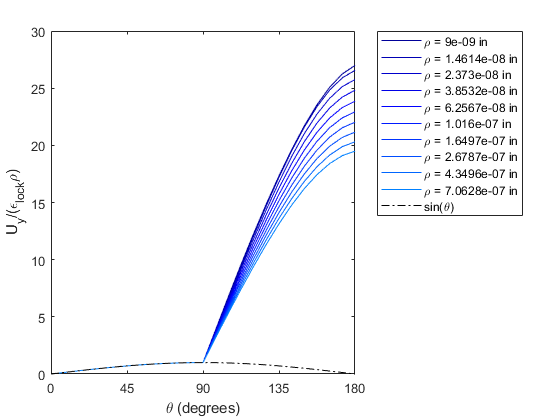


figure;
plotdata = [];
thetas = 0:180/(4*ndivs):180;
rhovals = vecnorm(nodes(:,rhos(:,1))-origin');
rhos_ind = rhos;
cmap = colormap(jet(size(rhos_ind,1)));
for r = 1:k
    for i = 1:size(rhos_ind,2)
        plotdata(i,:) = [thetas(i) U2(rhos_ind(r,i))/(vecnorm(nodes(:,rhos_ind(r,i))-origin')*elock)];
    end
    plot(plotdata(:,1),plotdata(:,2),'Color',cmap(r,:))
    hold on
end
plot(0:180,sin(deg2rad(0:180)),'k-.')
hold off
xlabel('\theta (degrees)')
ylabel('U_{y}/(\epsilon_{lock}\rho)')
xlim([0 180])
xticks(0:45:180)
legend(["\rho = "+string(vecnorm(nodes(:,rhos_ind(1:k,1))-origin'))+" in", 'sin(\theta)'],'Location',"bestoutside")

History Plots

ind = 0;
for i = 1:length(frames)
    ind = ind + 1;
    historyenodes{ind} = extrapnodesV1_4(Iorder, size(nodes,2), history{1,frames(i)}, elements);
    historysnodes{ind} = extrapnodesV1_4(Iorder, size(nodes,2), history{2,frames(i)}, elements);
    historyunodes{ind} = history{3,frames(i)};
end

%Plot of epsilon_y for theta = 0
% Computer average nodal strains (i) along theta = 0 for all history steps {j}
% collected
for j = 1:length(historyenodes)
    for i = 1:length(rhos(:,1))
        historyE2{j}(i) = sum(historyenodes{j}(2,elements==rhos(i,1)))/histcounts(elements(elements==rhos(i,1)));
        historyS2{j}(i) = sum(historysnodes{j}(2,elements==rhos(i,1)))/histcounts(elements(elements==rhos(i,1)));
        historyS1{j}(i) = mean(historysnodes{j}(1,elements==rhos(i,1)));
        historyU{j}(:,i) = historyunodes{j}(rhos(i,1)*2-1:(rhos(i,1)*2));
        
    end
end

refconfig = reshape(nodes-origin',1,[])';
for j = 1:length(historyenodes)
    for i = 1:length(rhos(:,1))
        historyXtheta180{j}(:,i) = historyunodes{j}(rhos(i,size(rhos,2))*2-1:(rhos(i,size(rhos,2))*2))...
            + refconfig(rhos(i,size(rhos,2))*2-1:(rhos(i,size(rhos,2))*2));
        
    end
end

for j = 1:length(historyenodes)
    for i = 1:length(rhos(:,1))
        historyutheta0{j}(:,i) = historyunodes{j}(rhos(i,1)*2-1:(rhos(i,1)*2));        
    end
end

% movielabel = ['trac' num2str(trac) 'matdir' num2str(mat_ndir) '_'];
% %Create avi movie of strain progression for theta = 0
% 
% figure;
% set(gca,'nextplot','replacechildren');
% set(gca,'XScale','log');
% xlabel('\rho (in)')
% ylabel('\epsilon_{y}(\theta = 0^\circ)')
% v = VideoWriter([movielabel 'eps_y.avi']);
% v.FrameRate = movieframerate;
% v.Quality = 100;
% open(v);
% 
% minrho = min(rhovals);
% maxrho = max(rhovals);
% for i = 1:length(frames)
%     plot((rhovals),historyE2{i}(:))
%     annotation('textbox', [.7 .7 .25 .12],'String',...
%         ['Load pct.: ' num2str(frames(i)/nsteps*100.,'%3.2f') '%' newline '\sigma_{\infty} = ' num2str(trac) ' (psi)'])
%     line([minrho maxrho],[0.1547 0.1547],'Color','red','LineStyle','--')
%     text(1e-5,(0.95*elock),['\epsilon_{lock} = ' num2str(elock)],'Color','red')
%     axis([0 maxrho 0 elock*1.05])
%     axis manual
%     
%     frame = getframe(gcf);
%     writeVideo(v,frame);
% end
% close(v);

% %Make loglog sigmay plot movie
% lockpercent = 0.99;
% 
% warning('off','all')
% 
% figure;
% set(gca,'nextplot','replacechildren');
% v = VideoWriter([movielabel 'loglog_y.avi']);
% v.FrameRate = movieframerate;
% v.Quality = 100;
% open(v);
% 
% for i = 2:length(frames)
%     loglog(rhovals,historyS2{i},'-x','Color','blue')
%     ft = fittype('m*x + b');
%     funlock = fit(log10(rhovals(historyE2{i}(:)<lockpercent*elock & historyE2{i}(:) > 0.25*elock))',log10(historyS2{i}(historyE2{i}(:)<lockpercent*elock & historyE2{i}(:) > 0.25*elock))',ft);
%     text(10e-3,10e7,['\lambda_{unlock} = ' num2str(funlock.m,'%1.3f') newline],'Color','blue')
%     axis([10e-10 10e0 10e0 10e10])
%     axis manual
%     hold on
%     %locked region
%     loglog(rhovals(historyE2{i}(:)>lockpercent*elock),historyS2{i}(historyE2{i}(:)>lockpercent*elock),'-x','Color','red')
%     loglog(rhovals(1:2),historyS2{i}(1:2),'-x','Color','black')
%     if length(rhovals(historyE2{i}(:)>lockpercent*elock)) >= 2
%         flock = fit(log10(rhovals(historyE2{i}(:)>lockpercent*elock))',log10(historyS2{i}(historyE2{i}(:)>lockpercent*elock))',ft);
%         text(10e-3,10e6,['\lambda_{lock} = ' num2str(flock.m,'%1.3f') newline],'Color','red')
%     end
%     if length(rhovals(historyE2{i}(:)>lockpercent*elock)) >= 2
%         flocktip = fit(log10(rhovals(1:2)'),log10(historyS2{i}(1:2))',ft);
%         text(10e-3,10e5,['\lambda_{crack tip} = ' num2str(flocktip.m,'%1.3f') newline],'Color','black')
%     end
%     hold off   
%     annotation('textbox', [.6 .78 .25 .12],'String',...
%         ['Load pct.: ' num2str(frames(i)/nsteps*100.,'%3.2f') '%' newline '\sigma_{\infty} = ' num2str(trac) ' (psi)'])
%     xlabel('\rho (in)')
%     ylabel('\sigma_{y} (psi)')  
%     frame = getframe(gcf);
%     writeVideo(v,frame);
% end
% close(v);

% 
% %Make loglog sigmax plot movie
% warning('off','all')
% 
% figure;
% set(gca,'nextplot','replacechildren');
% v = VideoWriter([movielabel 'loglog_x.avi']);
% v.FrameRate = movieframerate;
% v.Quality = 100;
% open(v);
% 
% for i = 2:length(frames)
%     loglog(rhovals,historyS1{i},'-x','Color','blue')
%     ft = fittype('m*x + b');
%     funlock = fit(log10(rhovals(historyE2{i}(:)<lockpercent*elock & historyE2{i}(:) > 0.25*elock))',log10(historyS1{i}(historyE2{i}(:)<lockpercent*elock & historyE2{i}(:) > 0.25*elock))',ft);
%     text(10e-8,10e9,['\lambda_{unlock} = ' num2str(funlock.m) newline],'Color','blue')
%     axis([10e-10 10e0 10e0 10e10])
%     axis manual
%     hold on
%     %locked region
%     loglog(rhovals(historyE2{i}(:)>lockpercent*elock),historyS1{i}(historyE2{i}(:)>lockpercent*elock),'-x','Color','red')
%     if length(rhovals(historyE2{i}(:)>lockpercent*elock)) >= 2
%         flock = fit(log10(rhovals(historyE2{i}(:)>lockpercent*elock))',log10(historyS1{i}(historyE2{i}(:)>lockpercent*elock))',ft);
%         text(10e-8,10e8,['\lambda_{lock} = ' num2str(flock.m) newline],'Color','red')
%     end
%     hold off   
%     annotation('textbox', [.6 .78 .25 .12],'String',...
%         ['Load pct.: ' num2str(frames(i)/nsteps*100.,'%3.2f') '%' newline '\sigma_{\infty} = ' num2str(trac) ' (psi)'])
%     xlabel('\rho (in)')
%     ylabel('\sigma_{x} (psi)')  
%     frame = getframe(gcf);
%     writeVideo(v,frame);
% end
% close(v);

%Create avi movie of crack face position
% 
% figure;
% set(gca,'nextplot','replacechildren');
% xlabel('x (in)')
% ylabel('y (in)')
% v = VideoWriter([movielabel 'X180.avi']);
% v.FrameRate = movieframerate;
% v.Quality = 100;
% open(v);
% 
% for i = 1:length(frames)
%     loglog(historyXtheta180{i}(1,:),historyXtheta180{i}(2,:),'-x')
%     annotation('textbox', [.7 .2 .25 .12],'String',...
%         ['Load pct.: ' num2str(frames(i)/nsteps*100.,'%3.2f') '%' newline '\sigma_{\infty} = ' num2str(trac) ' (psi)'])
%     axis([1e-8 max(historyXtheta180{length(historyXtheta180)}(1,:)) 1e-8  max(historyXtheta180{length(historyXtheta180)}(2,:))])
%     axis manual
% %     text(1e-6,1e-3,['Crack tip opening angle = ' num2str(2*rad2deg(atan(historyXtheta180{i}(2,1)/historyXtheta180{i}(1,1))),'%3.2f') '^{\circ}'],'Color','black')
%     frame = getframe(gcf);
%     writeVideo(v,frame);
% end
% close(v);
